# Taller II

### 29/03/2022 2022-01S

#### Métodos Númericos

#### Matrices

Se resuelven los ejercicios $\left.\left.\left.1\ldotp b\right),2\ldotp b\right),8\ldotp b\right),11$, se propone el uso de Jacobi, SOR y manipulación propiad de Matlab

**1.** Calcule $||x||_{\infty } ,||x||_1 ,||x||_2 ,$ para cada uno de los siguientes vectores.

**    b) **$x={\left\lbrack -2,3,4,-3,-1,2\right\rbrack }^T$

x = [-2, 3, 4, -3, -1, 2]';

% Hallamos las normas respectivas:
norm(x, 'inf'), norm(x, 1), norm(x)

**2.** Demuestre que las siguientes sucesiones son convergentes y encuentre sus límites:

**    b) **$x^{\left(k\right)} =\left\lbrack \frac{3\;k+1}{k^2 },\left(\frac{1}{k}\right)\ln \left(k\right),k^2 \;e^{-k} ,\;\frac{2\;k}{1+2k}\right\rbrack$

clear
syms x(k)
x(k) = [(3*k + 1)/k^2, log(k)/k, k^2 * exp(-k), 2*k / (1 + 2*k)];


ans = 4

ans = 15

ans = 6.5574

% Realicemos el límite:
limit(x, inf)

**8.** En cada caso, utilice los métodos de Jacobi y Gauss-Seidel para aproximar las soluciones de los sistemas lineales Ax = b. En todos los casos use el vector nulo como primera aproximación.

**    b) **$A=\left\lbrack \begin{array}{cccc}
4 & 1 & -1 & 1\\
1 & 4 & -1 & -1\\
-1 & -1 & 5 & 1\\
1 & -1 & 1 & 3
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
-2\\
-1\\
0\\
1
\end{array}\right\rbrack$

clear

% Trivialmente usemos los métodos:
A = [4 1 -1 1; 1 4 -1 -1; -1 -1 5 1; 1 -1 1 3];
b = [-2 -1 0 1]';
x0 = zeros(size(b));

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 1 \end{array}\right)$$


XJ = jacobi(A, b, x0, 1e-5, 40)
XGS = gseid(A, b, x0, 1e-5, 20)
norm(abs(XJ - XGS)) % Similares.

**11.** Sean $A=\left\lbrack \begin{array}{ccc}
1 & 0 & -1\\
-\frac{1}{2} & 1 & -\frac{1}{4}\\
1 & -\frac{1}{2} & 1
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
\frac{1}{5}\\
-1\ldotp 425\\
2
\end{array}\right\rbrack$

**    a. **Nos interesa resolver $\textrm{Ax}=b$ por los métodos de Jacobi y Gauss-Seidel. Demuestre que los dos métodos iterativos convergen.

**    b. **En lugar de $-1$ utilice $-2$ en la componente $\left(1,3\right)$ de $A$. ¿Siguen siendo convergentes los dos métodos?

clear

% Trivialmente usemos los métodos:
A = [1 0 -1; -1/2 1 -1/4; 1 -1/2 1];
b = [1/5 -1.425 2]';

k = 22

err = 1.0131e-05

relerr = 9.5441e-06

XJ =    -0.7534
    0.0411
   -0.2808
    0.6918


x0 = zeros(size(b));

k = 12

err = 9.3826e-06

relerr = 8.8391e-06

XGS =    -0.7534
    0.0411
   -0.2808
    0.6918


ans = 1.0981e-05

[TJ, TGS] = Jac_GS(A) % Convergencia asegurada
A(1, 3) = -2;
[TJ, TGS] = Jac_GS(A) % Convergencia no asegurada
XJ = jacobi(A, b, x0, 1e-5, 40) % Divergencia
XGS = gseid(A, b, x0, 1e-5, 20) % Divergencia

#### Sistemas lineales y no lineales    

Se resuelven los ejercicios $\left.2\ldotp b\right),4$, se propone el uso de Jacobi, SOR y Newton Multivariado

**2.** En cada caso, utilice el método de SOR con  $\omega =1,1:0,1:1,6$ (notación MATLAB) para aproximar las soluciones de los sistemas lineales $A\;x=b$. En todos los casos use máximo número de iteraciones igual a $\textrm{maxIter}=3000$, tolerancia $\textrm{delta}={10}^{-5}$ y el vector nulo como primera aproximación. Determine las normas de los vectores residual y error. Use la norma 2.

**    b) **$A=\textrm{gallery}\left(\prime {\textrm{dorr}}^{\prime } ,10\right)$ con $b=A*\textrm{ones}\left(10,1\right)$ y $p=\textrm{zeros}\left(10,1\right)$

**4. **Sea


$$A=\left\lbrack \begin{array}{ccc}
1 & \alpha  & \alpha \\
\alpha  & 1 & \alpha \\
\alpha  & \alpha  & 1
\end{array}\right\rbrack$$


Demuestre que A es positiva definida cuando $\alpha \;\in I=\left(-\frac{1}{2},1\right)$ y es estrictamente diagonalmente dominante para $\alpha \;\in J=\left(-\frac{1}{2},\;\frac{1}{2}\right)$. En la siguiente tabla escriba C, NC, NS si el respectivo método Converge, No Converge o No Sabe si converge o no converge.

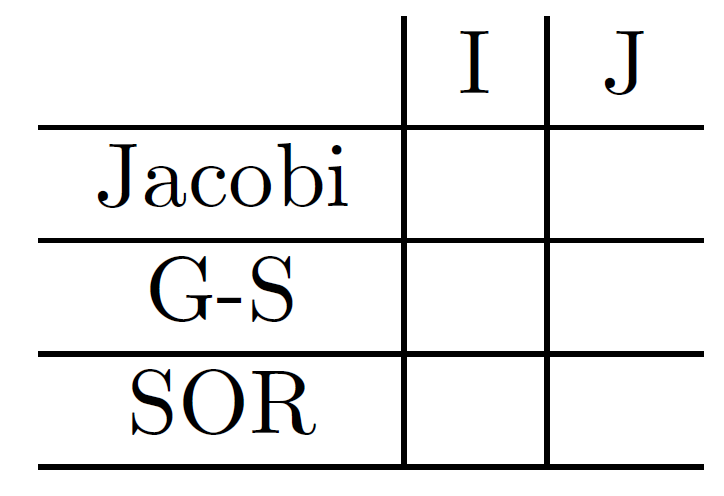

% Realicemos la primera definición:
clear
syms alpha lambda

A = [1 alpha alpha; alpha 1 alpha; alpha alpha 1];


No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.9721

ratioTGS = 0.6250

ratioTw = 0.6250

TJ =          0         0    1.0000
    0.5000         0    0.2500
   -1.0000    0.5000         0


TGS =          0         0    1.0000
         0         0    0.7500
         0         0   -0.6250


% Verifiquemos la confición de definida positiva:
PolCar = det(A - lambda*eye(size(A)))

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.3933

ratioTGS = 1.3750

ratioTw = 1.3750

TJ =          0         0    2.0000
    0.5000         0    0.2500
   -1.0000    0.5000         0


TGS =          0         0    2.0000
         0         0    1.2500
         0         0   -1.3750


solve(PolCar == 0, lambda)

k = 40

err = 1.2098e+06

relerr = 1.2461

XJ = 	1.0e+05 *

    9.6405
    0.9227
   -0.6934


Estos son los valores propios de la matriz, por lo cual sabemos que para la condición deben ser positivos:

de $1-\alpha$ tenemos que $\alpha \;<1$, y por otro lado de $2\alpha +1$, tenemos que $a>-\frac{1}{2}$

% Verificando si la función es edd, usamos que:

k = 20

err = 958.4494

relerr = 1.7264

XGS =   407.6659
  253.3412
 -278.9953


$1>2\;|\alpha |$, por lo cual obtenemos $J$

Revisemos la convergencia:

for I = -.5:.1:1
    B = eval(subs(A, alpha, I));
    [~] = Jac_GS(B)
end

$$PolCar = 2\,\alpha^{3}+3\,\alpha^{2}\,\lambda -3\,\alpha^{2}-\lambda^{3}+3\,\lambda^{2}-3\,\lambda +1$$

$$ans = \left(\begin{array}{c} 1-\alpha \\ 1-\alpha \\ 2\,\alpha +1 \end{array}\right)$$

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.0000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.8000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.6000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.4000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.2000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.2000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.4000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.6000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.8000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.0000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.2000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.4000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.6000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.8000

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 2.0000